% Initialisierung der Zustandsvariablen
R_0 = [0; 0; 0];  % Anfangsposition (Nullvektor)
V_0 = [0; 0; 0];  % Anfangsgeschwindigkeit (Nullvektor)

% Zeitbereich auf eine Minute erweitern
t = linspace(0, 120, 240);

% Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))];

% Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
V = cumtrapz(t/12, A, 2) + V_0;

% Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
R_pos = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

% Anzahl der Zeitschritte
N = length(t);

% Radarpositionen
pos_radar1 = [0, -10, 0];
pos_radar2 = [-50, 30, 0];
%x_k = [R_0; V_0];
% Zustandsvektor x_k (6-dimensional: [x, y, z, vx, vy, vz])
x_k = [R_pos(1,:); R_pos(2,:); R_pos(3,:); R_pos(1,:); R_pos(2,:); R_pos(3,:)];





% Prozessrauschkovarianzmatrix Q        (Annahme: Prozessrauschen ist 0, da wir noch keine weiteren Informationen haben)
Q = eye(6) * 0.001;

% Messrauschkovarianzmatrix R (Annahme: gleiche Varianzen für alle Beobachtungen)
standardabweichung = 0.1;
R = (standardabweichung^2) * eye(6);

% Zustandsübergangsmatrix F (Identity matrix as we assume constant velocity)
% Zeitschrittgröße
dt = t(2) - t(1);

% Zustandsübergangsmatrix F
F = [1 0 dt     0 dt 0;
     0 1  0    dt dt 0;
     0 0  1    0  0 0;
     0 0  0    1  0 0;
     0 0  0    0  1 dt;
     0 0  0    0  0 1]; 

% F = [eye(3), eye(3) * dt;
%      zeros(3), eye(3)];

% Schätzung der Anfangsvarianz des Zustandsvektors (Annahme: großer Wert, da wir wenig über den Anfangszustand wissen)
P = 1000 * eye(6);

messungen = [];
% EKF-Schätzung

for k = 2:N
    % Vorhersage
    x_k_pred = F * x_k(:, k-1);
    P_pred = F * P * F' + Q;
    % Update (Kalman Gain)
    H = create_observation_matrix(x_k_pred, pos_radar1, pos_radar2);
    K = P_pred * H' * inv(H * P_pred * H' + R);
    
    % Messungen
    z_k = [calculate_observations(x_k(:, k), pos_radar1); calculate_observations(x_k(:, k), pos_radar2)];
    
    messungen = [messungen, z_k];
    % Update der Zustandsschätzung und Fehlerkovarianz
    x_k(:, k) = x_k_pred + K * (z_k - [calculate_observations(x_k_pred, pos_radar1); calculate_observations(x_k_pred, pos_radar2)]);
    P = (eye(6) - K * H) * P_pred;
end

% Geschätzte Position des Helikopters
estimated_position = x_k(1:3, :)

estimated_position =          0    0.6501   -3.1233    3.2649   -1.2804    1.1628    0.1620    0.1369    0.8265    0.8727    1.2150    1.6685    2.3210    2.3361    2.3880    3.0465    3.5506    3.6052    4.2823    4.3537    4.5425    5.0868    5.6357    5.3835    5.6154    6.6487    6.4716    6.5221    7.1720    7.5259    7.8405    8.1951    8.8518    9.0462    9.2235   10.0132    9.7004   10.1973   10.3339   10.3239   10.4483   11.2247   11.2938   11.4191   11.1829   11.6894   11.6280   12.1624   11.8801   12.1509
         0    0.6016    0.6315    1.6503    1.6713    0.4713   -0.0755    0.2748    0.0669    0.3331    0.7431    1.3650    1.0917    1.4429    1.5341    1.4492    1.1467    1.7477    1.6478    1.7597    2.0615    2.1316    1.9381    2.4357    2.4803    1.9279    2.0938    2.4504    2.6803    2.5133    3.3082    3.1026    3.3963    3.7351    4.2369    3.4279    4.1942    4.2561    4.4274    5.5194    5.5571    5.6661    6.1400    6.2928    7.2367    7.9471    8.4575    8.79

% Funktion zur Berechnung der Beobachtungen (Messmodell)

messungen    

messungen =    10.4433    9.9157    9.9948    9.5471    9.8280    9.7852   10.0925    9.6881    9.9303   10.5525   10.6971   10.4035   10.6133   10.0530   10.8627   10.8004   11.3885   11.3494   11.8689   11.7038   12.3500   11.9500   12.7659   12.9121   12.6784   13.5250   13.9844   14.3602   14.0752   15.2470   15.3871   15.9636   16.5505   16.8328   16.6796   17.8642   18.0922   18.0092   18.8102   19.1463   19.8884   19.9740   20.4419   21.2085   21.8515   21.8614   22.8811   22.4958   22.8535   23.8011
   89.9348   89.7396   89.4150   88.9625   88.3845   87.6839   86.8650   85.9332   84.8952   83.7589   82.5336   81.2301   79.8600   78.4362   76.9723   75.4823   73.9805   72.4807   70.9964   69.5402   68.1236   66.7569   65.4487   64.2066   63.0365   61.9429   60.9293   59.9977   59.1494   58.3848   57.7033   57.1043   56.5861   56.1472   55.7857   55.4994   55.2862   55.1439   55.0704   55.0634   55.1210   55.2412   55.4221   55.6620   55.9592   56.3123   56.7197   57.1803   57.6

x_k_new_arr = [];
for i=1:length(messungen(1,:))
    x_k_new1 = x_k(1,i) - pos_radar1(1);
    x_k_new2 = x_k(1,i) - pos_radar1(2);
    x_k_new3 = x_k(1,i) - pos_radar1(3);
    x_k_new4 = x_k(1,i) - pos_radar2(1);
    x_k_new5 = x_k(1,i) - pos_radar2(2);
    x_k_new6 = x_k(1,i) - pos_radar2(3);
    x_k_new_arr = [x_k_new_arr; x_k_new1,x_k_new2,x_k_new3, x_k_new4,x_k_new5,x_k_new6];

end
transpose(x_k_new_arr)

ans =          0    0.6501   -3.1233    3.2649   -1.2804    1.1628    0.1620    0.1369    0.8265    0.8727    1.2150    1.6685    2.3210    2.3361    2.3880    3.0465    3.5506    3.6052    4.2823    4.3537    4.5425    5.0868    5.6357    5.3835    5.6154    6.6487    6.4716    6.5221    7.1720    7.5259    7.8405    8.1951    8.8518    9.0462    9.2235   10.0132    9.7004   10.1973   10.3339   10.3239   10.4483   11.2247   11.2938   11.4191   11.1829   11.6894   11.6280   12.1624   11.8801   12.1509
   10.0000   10.6501    6.8767   13.2649    8.7196   11.1628   10.1620   10.1369   10.8265   10.8727   11.2150   11.6685   12.3210   12.3361   12.3880   13.0465   13.5506   13.6052   14.2823   14.3537   14.5425   15.0868   15.6357   15.3835   15.6154   16.6487   16.4716   16.5221   17.1720   17.5259   17.8405   18.1951   18.8518   19.0462   19.2235   20.0132   19.7004   20.1973   20.3339   20.3239   20.4483   21.2247   21.2938   21.4191   21.1829   21.6894   21.6280   22.1624   21.8801   

messungen_kartesisch = get_kartesische_Koordianten(messungen)

kartesische_koordinaten =     0.0119   10.4433    0.0006   50.0429  -30.0188    0.0006
    0.0451    9.9156    0.0023   49.7305  -29.8103    0.0023
    0.1020    9.9943    0.0051   49.8173  -29.8264    0.0051
    0.1729    9.5455    0.0087   50.0919  -29.9392    0.0091
    0.2771    9.8241    0.0140   50.3970  -30.0539    0.0143
    0.3954    9.7771    0.0200   50.1644  -29.8317    0.0204
    0.5519   10.0774    0.0280   50.2949  -29.8093    0.0277
    0.6871    9.6637    0.0350   50.7699  -29.9734    0.0365
    0.8836    9.8908    0.0452   50.9425  -29.9409    0.0461
    1.1472   10.4898    0.0590   50.8784  -29.7525    0.0566


messungen_kartesisch =     0.0119    0.0451    0.1020    0.1729    0.2771    0.3954    0.5519    0.6871    0.8836    1.1472    1.3900    1.5861    1.8684    2.0151    2.4485    2.7072    3.1425    3.4160    3.8642    4.0903    4.6006    4.7147    5.3028    5.6166    5.7466    6.3589    6.7918    7.1770    7.2139    7.9880    8.2162    8.6642    9.1074    9.3696    9.3710   10.1097   10.2935   10.2824   10.7589   10.9524   11.3598   11.3737   11.5863   11.9469   12.2146   12.1076   12.5359   12.1725   12.1931   12.4996
   10.4433    9.9156    9.9943    9.5455    9.8241    9.7771   10.0774    9.6637    9.8908   10.4898   10.6062   10.2815   10.4471    9.8484   10.5823   10.4546   10.9450   10.8215   11.2202   10.9634   11.4581   10.9773   11.6083   11.6218   11.2961   11.9306   12.2171   12.4298   12.0771   12.9766   12.9984   13.3949   13.8049   13.9683   13.7817   14.7093   14.8580   14.7636   15.4056   15.6785   16.2967   16.3897   16.8092   17.4886   18.0812   18.1630   19.0984   18.

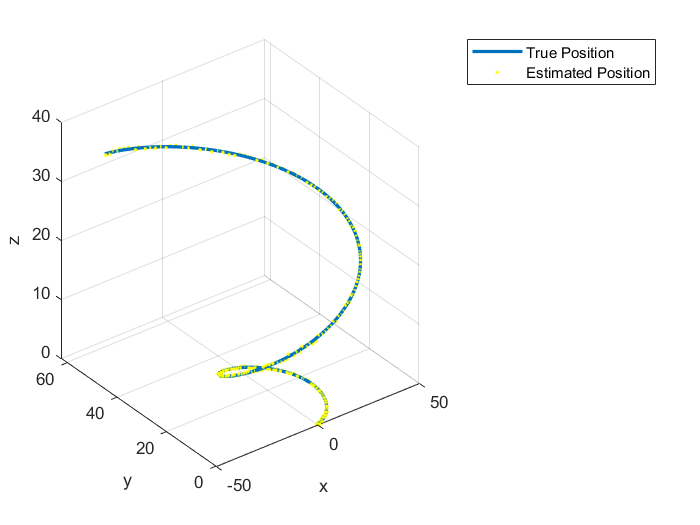

% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
%plot3(estimated_position(1, :), estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);
plot3(messungen_kartesisch(1, :), messungen_kartesisch(2, :)-10, messungen_kartesisch(3, :), 'y.', 'MarkerSize', 5);
%plot3(messungen_kartesisch(4, :), messungen_kartesisch(5, :), messungen_kartesisch(6, :), 'r.', 'MarkerSize', 5);
hold off;
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
legend('True Position', 'Estimated Position', 'Messungen Radar 1', 'Messungen Radar 2');

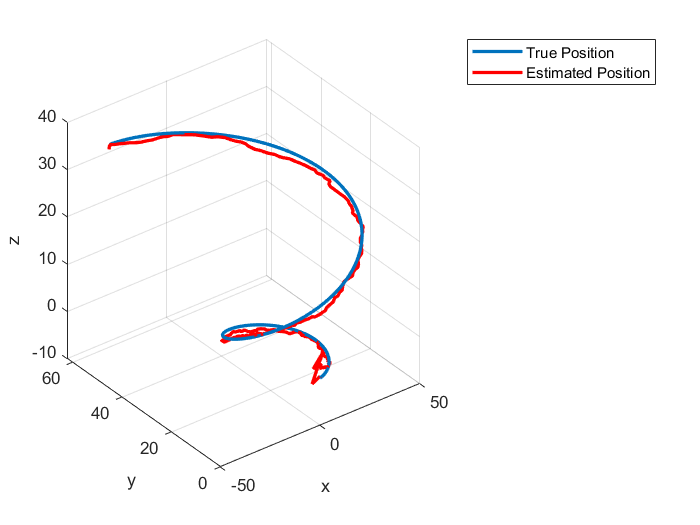



% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(estimated_position(1, :), estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);

hold off;
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
legend('True Position', 'Estimated Position');

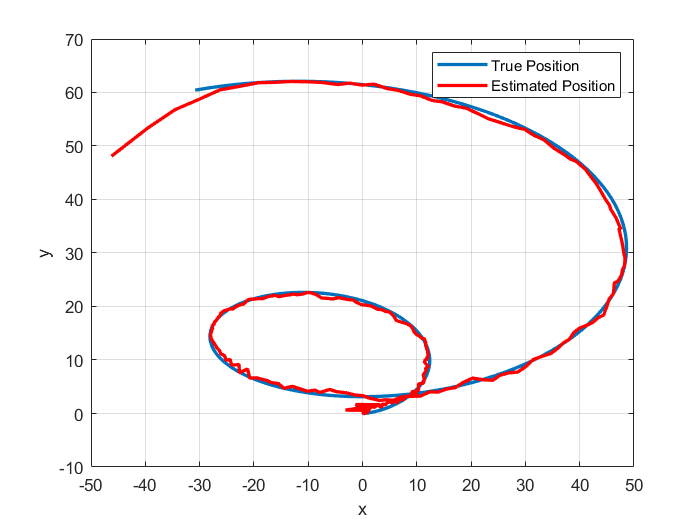


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot(R_pos(1,:), R_pos(2,:), 'LineWidth', 2);
hold on;
plot(estimated_position(1, :), estimated_position(2, :), 'r', 'LineWidth', 2);

hold off;
xlabel('x');
ylabel('y');
grid on;
legend('True Position', 'Estimated Position');

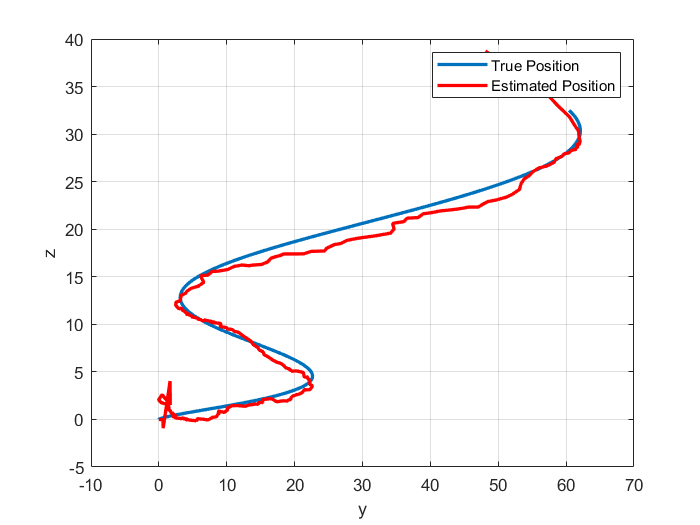



figure(1);
plot(R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);

hold off;
xlabel('y');
ylabel('z');
grid on;
legend('True Position', 'Estimated Position');

function obs = calculate_observations(x_k, pos_radar)
    
    dist_matrix_radar1 = [];
    phi_radar1 = [];
    theta_radar1 = [];

    zufallswerte_dist = rand(1, 1);
    
    % Skaliere und verschiebe die Werte, um den Bereich von -0.5 bis 0.5 zu erhalten
    zufallswerte_skaliert = zufallswerte_dist - 0.5;

    R_transposed = transpose(x_k);
    for i=1:length(R_transposed(:,1))
        dist_radar1 = norm(R_transposed(1:3) - pos_radar)+zufallswerte_skaliert;  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar
        dist_matrix_radar1 = [dist_matrix_radar1; dist_radar1]; 
        % Berechnung des Elevationswinkels (phi) für Radar 1
        delta_z = R_transposed(3) - pos_radar(3);
        rho = sqrt((R_transposed(1) - pos_radar(1))^2 + (R_transposed(2) - pos_radar(2))^2 + delta_z^2);
        phi_radar1 = [phi_radar1;rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar1 hinzu
        
        % Berechnung des Azimutwinkels (theta) für Radar 1
        delta_x = R_transposed(1) - pos_radar(1);
        delta_y = R_transposed(2) - pos_radar(2);
        theta_radar1 = [theta_radar1; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar1 hinzu
    end 



    polar_koordinaten_radar1 = [dist_matrix_radar1, theta_radar1, phi_radar1];
    
    obs = transpose(polar_koordinaten_radar1);

end

function messungen = messungen_anpassen(x_k, pos_radar1, pos_radar2)

    x_k_new_arr = [];
    for i=1:length(x_k(1,:))
        x_k_new1 = x_k(1,i) - pos_radar1(1);
        x_k_new2 = x_k(1,i) - pos_radar1(2);
        x_k_new3 = x_k(1,i) - pos_radar1(3);
        x_k_new4 = x_k(1,i) - pos_radar2(1);
        x_k_new5 = x_k(1,i) - pos_radar2(2);
        x_k_new6 = x_k(1,i) - pos_radar2(3);
        x_k_new_arr = [x_k_new_arr; x_k_new1,x_k_new2,x_k_new3, x_k_new4,x_k_new5,x_k_new6];
    
    end
    messungen = transpose(x_k_new_arr);
end


function H = create_observation_matrix22(x_k, pos_radar1, pos_radar2)
    x = x_k;
    dx = x(1) - pos_radar1(1);
    dy = x(2) - pos_radar1(2);
    dz = x(3) - pos_radar1(3);
    d = sqrt(dx^2 + dy^2 + dz^2);
    dxy = sqrt(dx^2 + dy^2);

    H = zeros(6, 6);
    H(1,1) = dx / d;
    H(1,2) = dy / d;
    H(1,3) = dz / d;
    H(2,1) = -dy / dxy^2;
    H(2,2) = dx / dxy^2;
    H(3,1) = dx * dz / (d^2 * dxy);
    H(3,2) = dy * dz / (d^2 * dxy);
    H(3,3) = -dxy / d^2;

    dx = x(1) - pos_radar2(1);
    dy = x(2) - pos_radar2(2);
    dz = x(3) - pos_radar2(3);
    d = sqrt(dx^2 + dy^2 + dz^2);
    dxy = sqrt(dx^2 + dy^2);

    H(4,4) = dx / d;
    H(4,5) = dy / d;
    H(4,6) = dz / d;
    H(5,4) = -dy / dxy^2;
    H(5,5) = dx / dxy^2;
    H(6,4) = dx * dz / (d^2 * dxy);
    H(6,5) = dy * dz / (d^2 * dxy);
    H(6,6) = -dxy / d^2;
end

function H = create_observation_matrix(x_k, pos_radar1, pos_radar2)
    H = zeros(6, 6);
    H(1:3, 1:3) = eye(3);
    H(4:6, 4:6) = eye(3);

    obs_radar1 = calculate_observations(x_k, pos_radar1);
    obs_radar2 = calculate_observations(x_k, pos_radar2);

    % Beobachtung 1 (Abstand zu pos_radar1)
    dxyz = x_k(1:3, 1)' - pos_radar1;
    H(1, 1:3) = dxyz / obs_radar1(1);

    % Beobachtung 2 (Azimutwinkel zu pos_radar1)
    dxy = dxyz(1:2);
    H(2, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;

    % Beobachtung 3 (Elevationswinkel zu pos_radar1)
    H(3, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar1(3) * norm(dxyz)^3);

    % Beobachtung 4 (Abstand zu pos_radar2)
    dxyz = x_k(1:3, 1)' - pos_radar2;
    H(4, 1:3) = dxyz / obs_radar2(1);

    % Beobachtung 5 (Azimutwinkel zu pos_radar2)
    dxy = dxyz(1:2);
    H(5, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;

    % Beobachtung 6 (Elevationswinkel zu pos_radar2)
    H(6, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar2(3) * norm(dxyz)^3);
end


function kartesische_koordinaten_radar = get_kartesische_Koordianten(polar_koordinaten_radar)
    
    polar_koordinaten_radar = transpose(polar_koordinaten_radar);
    x_list1 = [];
    y_list1 = [];
    z_list1 = [];
    x_list2 = [];
    y_list2 = [];
    z_list2 = [];
    

    for i = 1:length(polar_koordinaten_radar(:,1))
        % Berechnung der kartesischen Koordinaten für Radar 1
        x_radar1 = polar_koordinaten_radar(i, 1) .* sin(deg2rad(polar_koordinaten_radar(i, 3))) .* cos(deg2rad(polar_koordinaten_radar(i, 2)));
        y_radar1 = polar_koordinaten_radar(i, 1) .* sin(deg2rad(polar_koordinaten_radar(i, 3))) .* sin(deg2rad(polar_koordinaten_radar(i, 2)));
        z_radar1 = polar_koordinaten_radar(i, 1) .* cos(deg2rad(polar_koordinaten_radar(i, 3)));
        x_list1 = [x_list1; x_radar1];
        y_list1 = [y_list1; y_radar1];
        z_list1 = [z_list1; z_radar1];

        
        % Berechnung der kartesischen Koordinaten für Radar 2
        x_radar2 = polar_koordinaten_radar(i, 4) .* sin(deg2rad(polar_koordinaten_radar(i, 6))) .* cos(deg2rad(polar_koordinaten_radar(i, 5)));
        y_radar2 = polar_koordinaten_radar(i, 4) .* sin(deg2rad(polar_koordinaten_radar(i, 6))) .* sin(deg2rad(polar_koordinaten_radar(i, 5)));
        z_radar2 = polar_koordinaten_radar(i, 4) .* cos(deg2rad(polar_koordinaten_radar(i, 6)));
        x_list2 = [x_list2; x_radar2];
        y_list2 = [y_list2; y_radar2];
        z_list2 = [z_list2; z_radar2];

    end
    % Kombinieren der kartesischen Koordinaten für Radar 1
    kartesische_koordinaten = [x_list1, y_list1, z_list1, x_list2, y_list2, z_list2]
    kartesische_koordinaten_radar = transpose(kartesische_koordinaten);


end